# get_seismoc_width  - prelim results

## Create data:

MSseismo = get_seismo_width(); 
load mainshock_info.mat

## Overview:

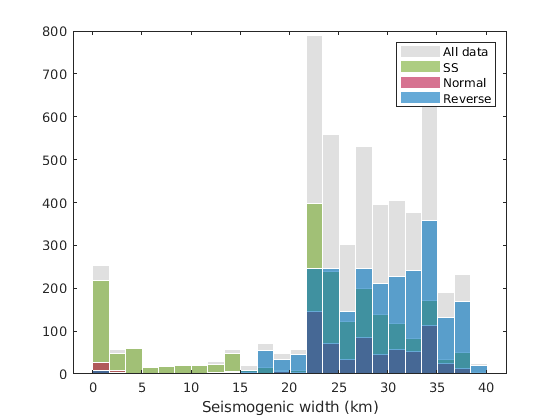

figure 

hist_fms(MSseismo, MSfms, 'Seismogenic Width (km)') 
xlabel('Seismogenic width (km)')

## Sensitivity test:

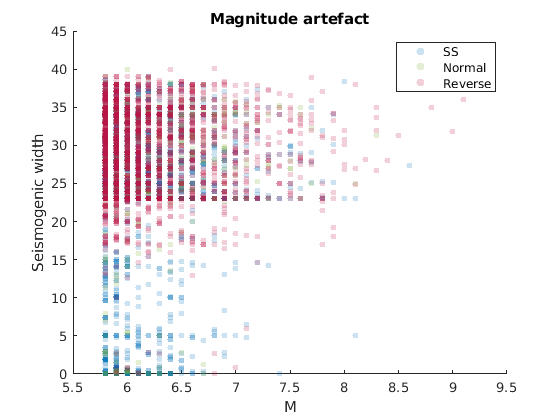

figure
for n = 1:3
    I = MSfms == n; 
    scatter(MSmag(I),MSseismo(I),20,'filled','MarkerFaceAlpha',0.2)
    hold on
end
xlabel('M')
ylabel('Seismogenic width')
legend({'SS','Normal','Reverse'})
title('Magnitude artefact')

test res

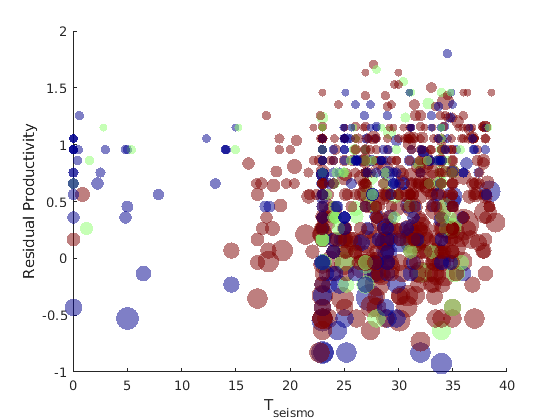

figure
I = MSmag>5;
scatter(MSseismo(I),MSres(I),(MSmag(I)-3).^3.5,MSfms(I),'filled','MarkerFaceAlpha',0.5)
colormap jet
xlabel('T_{seismo}')
ylabel('Residual Productivity')

Correct for magnitude

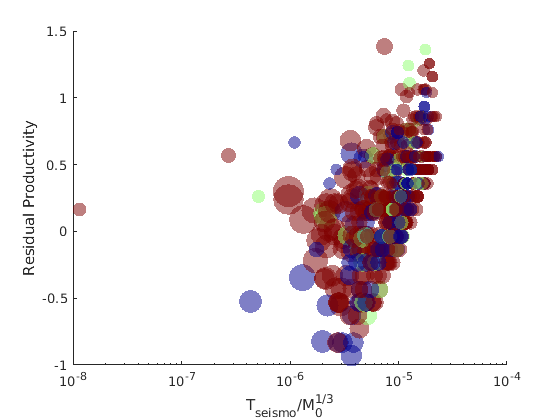


figure
I = MSmag>6.3;
Mo = (10.^(3/2*(MSmag + 10.7)))/10^7;
L = (Mo).^(1/3);
Lnorm = MSseismo./L;
scatter(Lnorm(I),MSres(I),(MSmag(I)-3).^3.5,MSfms(I),'filled','MarkerFaceAlpha',0.5)
colormap jet
xlabel('T_{seismo}/M_0^{1/3}')
ylabel('Residual Productivity')
set(gca,'XScale','log')

reality checks

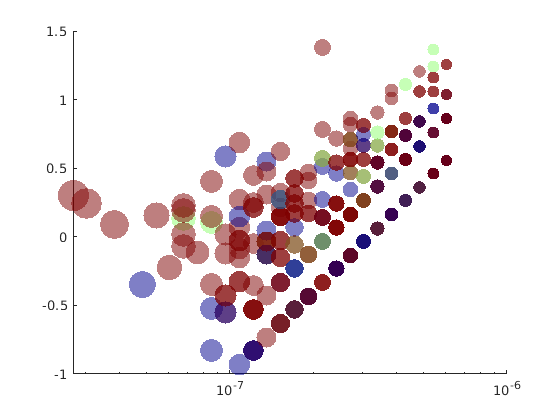

figure
scatter(1./Mo(I).^(1/3),MSres(I),(MSmag(I)-3).^3.5,MSfms(I),'filled','MarkerFaceAlpha',0.5)
colormap jet
set(gca,'XScale','log')

## Subfunctions

function hist_fms(MSX,fms,xLabel)
figure
resRange    = minmax(MSX');
binEdges    = linspace(resRange(1),resRange(2),3*log(length(MSX)));
histogram(MSX,binEdges,'FaceColor', [0.8 0.8 0.8],'EdgeColor',[1 1 1])
hold on
for n = 1:3
    I = fms == n;
    histogram(MSX(I),binEdges,'EdgeColor',[1 1 1])
end
xlabel(xLabel)
legend({'All data', 'SS', 'Normal', 'Reverse'})

end